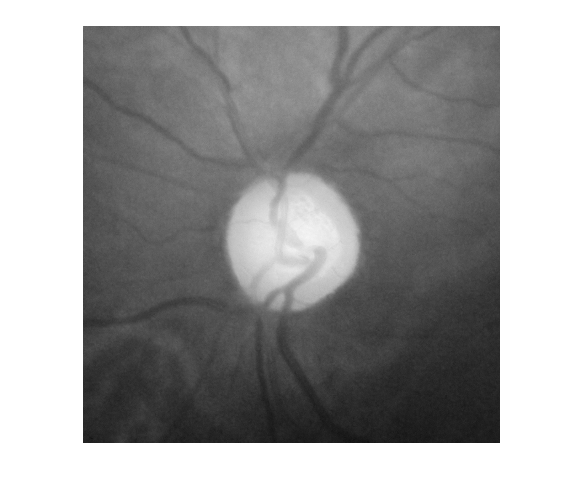

%Open file
[image, pathname] = uigetfile('*.png');
J = imread(image);

%Crop gambar untuk menghilangkan border hitam pada gambar asli
I = imcrop(J,[350 350 1250 1250]);
HSV = rgb2hsv(I);

%%Cek RGB
R = I(:,:,1);
G = I(:,:,2);
B = I(:,:,2);

figure, imshow(R)

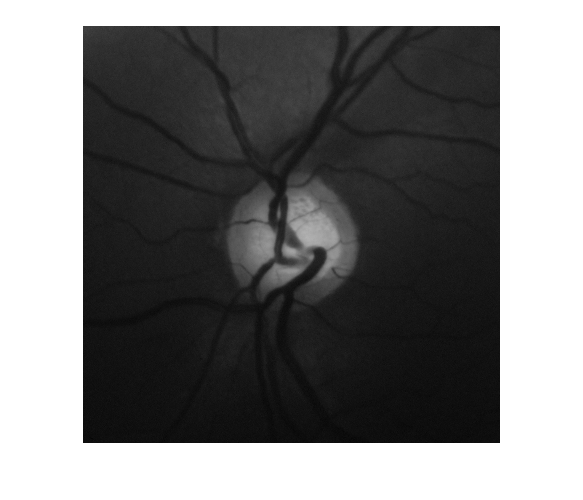

figure, imshow(G)

figure, imshow(B)

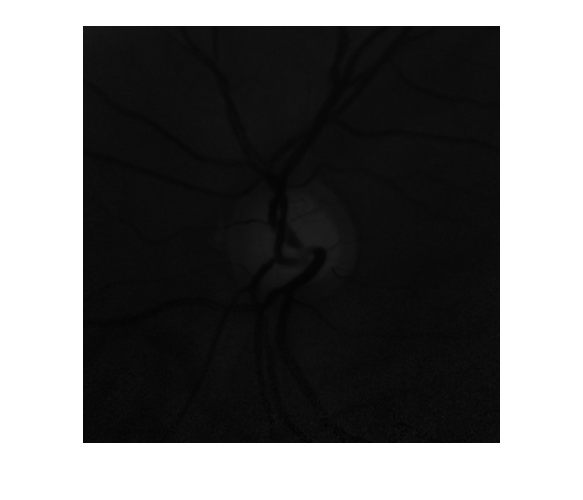


%%Cek HSV
H = HSV(:,:,1);
S = HSV(:,:,2);
V = HSV(:,:,3);

figure, imshow(H)

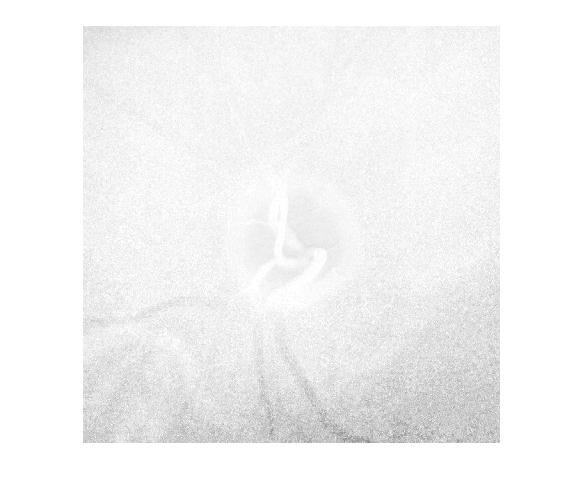

figure, imshow(S)

figure, imshow(V)

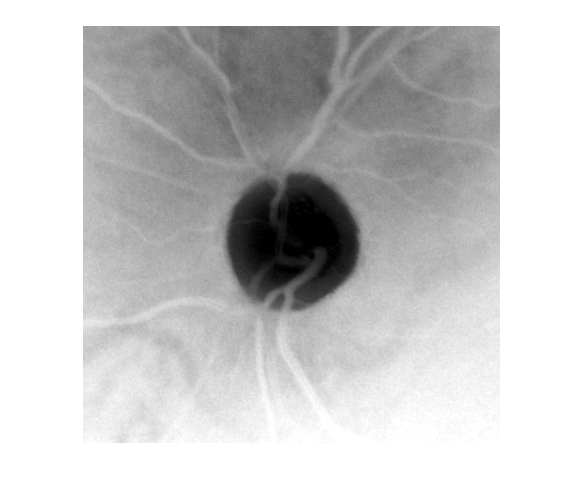


%Disimpulkan untuk lokalisasi dan segmentasi menggunakan nilai Value citra
%Ambil value citra
%Invert warna
figure, imshow(imcomplement(imadjust(V)))

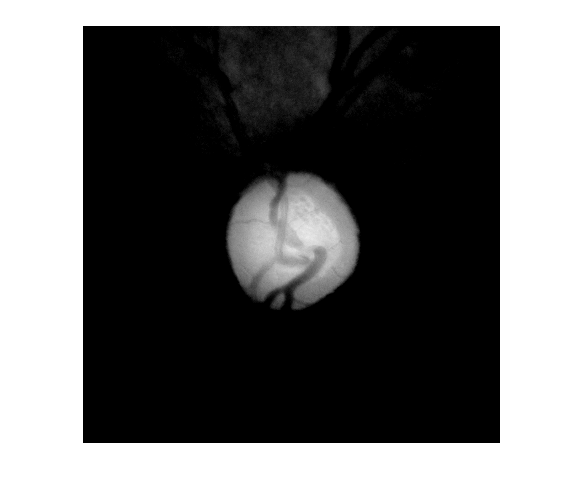

%Mengubah kontras citra gray
Vnew = V - imcomplement(V);
figure, imshow(Vnew)

level = graythresh(V);
%Vnew = imadjust(Vnew);
ne = Vnew > level;
binaryImage = ne;
% Get rid of stuff touching the border
binaryImage = imclearborder(binaryImage);
fill = imfill(binaryImage,'holes');

se = strel('disk', 6)

se = strel is a disk shaped structuring element with properties:

      Neighborhood: [11×11 logical]
    Dimensionality: 2


dil = imdilate(fill,se)

dil = 1251×1251 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

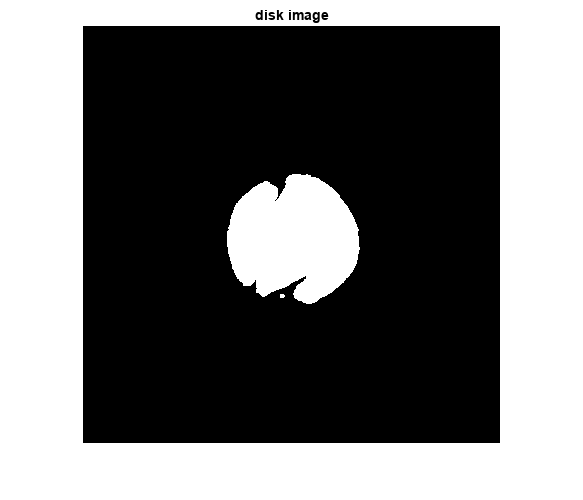

figure,imshow(dil)
title('disk image')


N = nnz(dil);
fprintf('Luas OD = %i Pixel\n', N)

Luas OD = 115441 Pixel



openim = imclose((imopen(dil, strel('diamond',25))), strel('arbitrary',40))

openim = 1251×1251 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

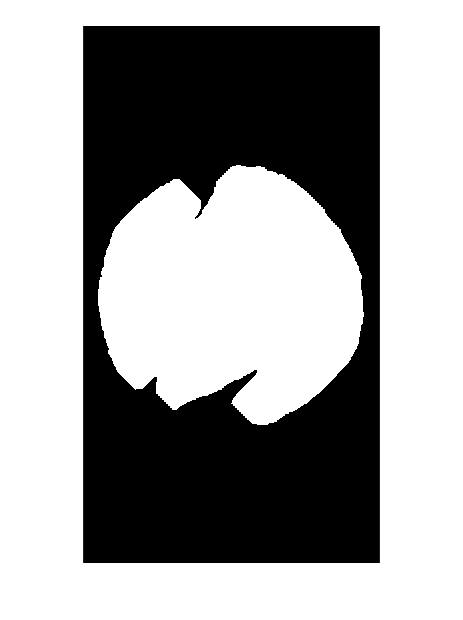

% Extract only the two largest blobs.
BW = binaryImage;
CC = bwconncomp(BW);
numPixels = cellfun(@numel,CC.PixelIdxList);
[biggest,idx] = max(numPixels);
BW(CC.PixelIdxList{idx}) = 0;
filteredForeground = BW;

% regionprops untuk mendapatkan informasi Area, Centroid, Bbox
s = regionprops(dil,'basic');
centroids = cat(1,s.Centroid);
bbox = cat(1,s.BoundingBox);
x = s(1).Centroid(1,1) - 1/2*(bbox(3));
y = s(1).Centroid(1,2) - 1/2*(bbox(4));
figure, imshow(imcrop(openim, [x y bbox(3) bbox(4)]))

fprintf('Panjang (x) Bounding Box = %i Pixel\n', bbox(3))

Panjang (x) Bounding Box = 4.445000e+02 Pixel


fprintf('Panjang (y) Bounding Box = %i Pixel\n', bbox(4))

Panjang (y) Bounding Box = 8.045000e+02 Pixel


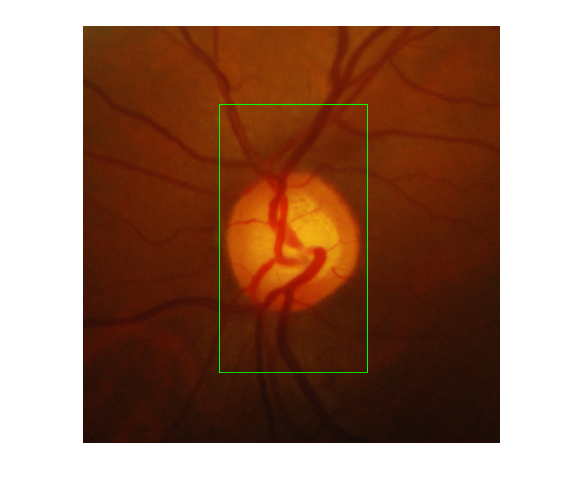


figure, imshow(I)
rectangle('Position',[x y bbox(3) bbox(4)],'EdgeColor','g')

%hold off
% Hitung Area, Luas BoundingBox, Titik tengah
fprintf('Area = %i Pixel\n', s(1).Area);

Area = 115279 Pixel


fprintf('Luas = %i Pixel^2\n', bbox(3)*bbox(4));

Luas = 3.576002e+05 Pixel^2


fprintf('Titik Pusat = (%i, %i) Pixel\n', s(1).Centroid(1,1), s(1).Centroid(1,2));

Titik Pusat = (6.319745e+02, 6.381401e+02) Pixel



% figure, imshow(BW);
% % Fill holes in the blobs to make them solid.
%binaryImage = imfill(binaryImage, 'holes');
% % Display the binary image.
%dis(:,:,1)=immultiply(binaryImage,I(:,:,1));
%dis(:,:,2)=immultiply(binaryImage,I(:,:,2));
%dis(:,:,3)=immultiply(binaryImage,I(:,:,3));
%a = dil;
%stats = regionprops(double(a),'Centroid',...
%    'MajorAxisLength','MinorAxisLength')
%centers = stats.Centroid;
%diameters = mean([stats.MajorAxisLength stats.MinorAxisLength],2);
%radii = diameters/2;
% Plot the circles.
% figure,imshow(I)
%hold on
%viscircles(centers,radii);
%hold off

%Menentukan Luas OC
crpd = imcrop(I, [x y bbox(3) bbox(4)])

crpd = 805×445×3 uint8 array
crpd(:,:,1) =

   131   133   134   131   130   133   132   132   133   134   134   135   136   137   135   134   135   134   132   132   133   133   126   124   125   125   124   122   122   124   124   124   124   126   130   130   132   133   130   129   131   128   127   130   129   132   131   134   136   138   140   144   146   147   148   150   149   146   144   139   138   141   141   141   140   140   141   141   139   138   138   141   141   140   140   141   140   139   137   138   139   138   138   138   138   137   140   140   141   140   139   140   141   141   143   144   139   137   142   145   142   140   140   138   135   137   141   141   139   140   142   142   140   139   141   141   141   142   141   140   140   142   144   142   142   143   144   139   142   144   142   144   145   142   136   138   137   137   139   137   138   141   139   136   140   137   136   137   135   138   140   143   145   145   144   149   149   147   147  

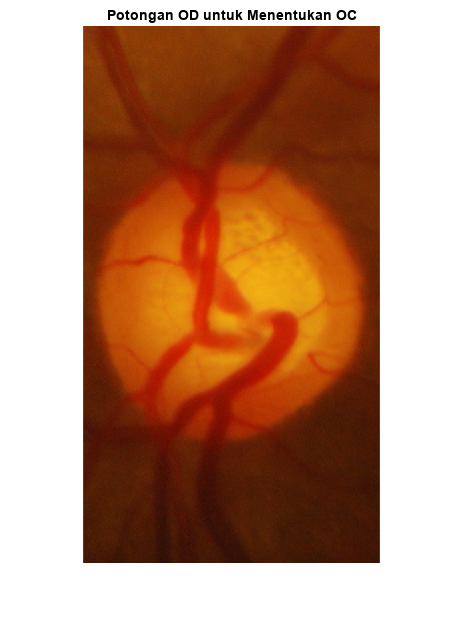

figure, imshow(crpd)
title('Potongan OD untuk Menentukan OC');

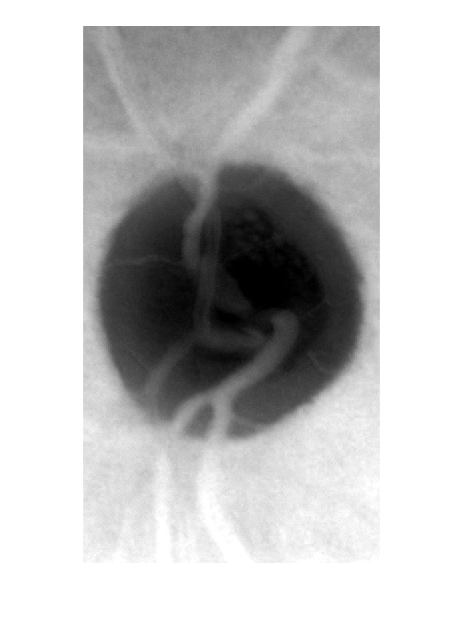


%Invert warna
HSV = rgb2hsv(crpd);
V2 = HSV(:,:,3);
figure, imshow(imcomplement(imadjust(V2)))

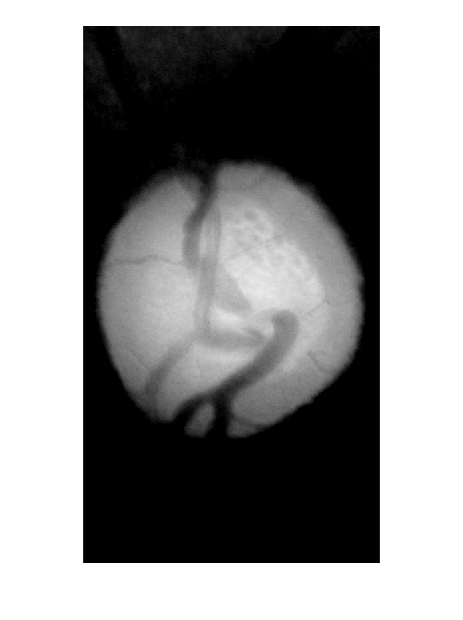

%Mengubah kontras citra gray
V2new = V2 - imcomplement(V2);
figure, imshow(V2new)

level2 = graythresh(V2);
%Vnew = imadjust(Vnew);
ne = V2new > level2;
binaryImage = ne;
% Get rid of stuff touching the border
binaryImage = imclearborder(binaryImage);
fill = imfill(binaryImage,'holes');

se = strel('disk', 8)

se = strel is a disk shaped structuring element with properties:

      Neighborhood: [15×15 logical]
    Dimensionality: 2


cup = imdilate(fill,se)

cup = 805×445 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

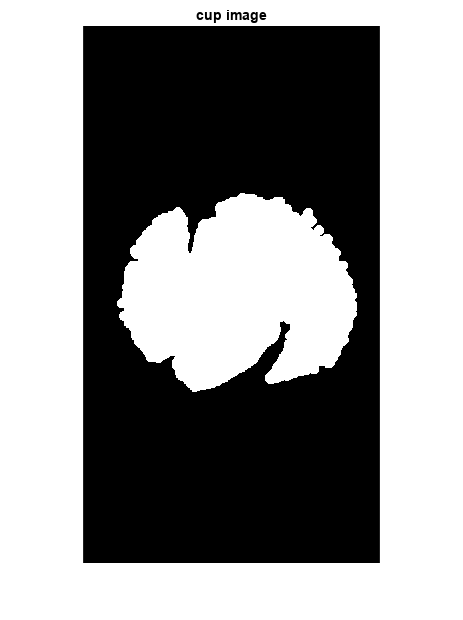

figure,imshow(cup)
title('cup image')